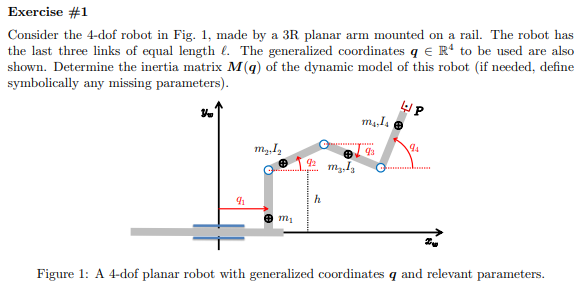

% % % This part is isolated from previous section
% % clear;clc
% %
% % % syms k q1(t) q2(t) q3(t)
% sigma = [1,0,0,0];
% R2Robot=['prrr';'xxxx';sigma]
% n = length(sigma);
% % t = sym('t', 'real');
% q = sym('q_', [n 1],'real');
% qd = sym('q_dot_', [n 1],'real');
% qdd = sym('q_ddot_', [n 1],'real');
% %
% dc = sym('dc_', [n 1],'real');
% % k = sym('k', [n 1],'real');
% l = sym('l_', [n 1],'real');
% m = sym('m_', [n 1],'real');
% I = sym('I_', [n 1],'real');
% alpha_angle=sym('alpha','real')
% g0 = sym('g0','real');
% g=[0,g0,0]';
% 
% 
% z = Gen_param(n);
% z.sigmaD=R2Robot;
% z.l=l;
% z.q=q;
% z.q_dot=qd;
% z.dc=dc;
% z.m=m;
% z.I=I;
% z.methodD=1;
% % z.dhTable=[]
% z.firstParam='alpha';
% % z.rc=[];
% % z.movingframes=[];
% z.angle_=sym(zeros(1,n));
% l_0=sym('l','real');
% z.opt_expr={l,[l_0,l_0,l_0,l_0]'};%not necessary
% 
% % z.rcdefined=true;

## axis offset

% % 
% h=sym('h','real')
% %x,y,z
% z.xyx_offset=sym(zeros(3,n));
% z.xyx_offset(:,1)=[0,h,0]';%

% %Global q reference?
% % clear
% % z.q_global
% z.global_q_reference=true;
% if(z.global_q_reference)
%     [z.q_global,z.q_dot_global]=convert_local2global_q(z.q,z.q_dot,z.sigmaD);
% end

% 
% %
% %
% % xyonly=true
% % [f,J,V,J_ps,PCVar,PC_EEShort,VarShortRobot]= getGenericPC_EE2(R2Robot,l,q,qd,dc,m,I,xyonly)
% % VarShortRobot.M
% % angle_desired=[0,0]
% % l(1)=0
% [Pc,vc,w,T,Ti,M,VarShortRobot,Trans] = getGenericPC2(z);

% M
% Pc
% simplify((Ti'))
% vc
% simplify(Trans.PTotal)
% Trans.PPartial{:}


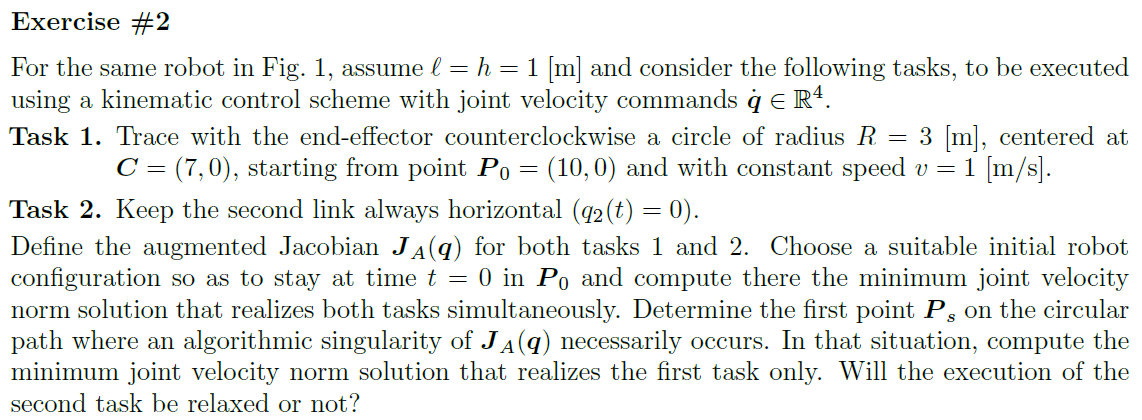

% % This part is isolated from previous section
% clear;clc
% 
% % syms k q1(t) q2(t) q3(t)
% sigma = [1,0,0,0];
% R2Robot=['prrr';'xxxx';sigma]
% n = length(sigma);
% % t = sym('t', 'real');
% q = sym('q_', [n 1],'real');
% qd = sym('q_dot_', [n 1],'real');
% qdd = sym('q_ddot_', [n 1],'real');
% %
% dc = sym('dc_', [n 1],'real');
% % k = sym('k', [n 1],'real');
% l = sym('l_', [n 1],'real');
% m = sym('m_', [n 1],'real');
% I = sym('I_', [n 1],'real');
% alpha_angle=sym('alpha','real')
% g0 = sym('g0','real');
% g=[g0,0,0]';
% 
% z = Gen_param(n);
% z.sigmaD=R2Robot;
% z.l=l;
% z.q=q;
% z.q_dot=qd;
% z.dc=dc;
% z.m=m;
% z.I=I;
% z.methodD=1;
% % z.dhTable=[]
% z.firstParam='alpha';
% % z.rc=[];
% % z.movingframes=[];
% z.angle_=sym(zeros(1,n));
% l_0=sym("l","real");
% % l_0=1%sym('l','real')
% h=sym('h','real');
% h_=h%1;
% z.opt_expr={[l;h],[l_0,l_0,l_0,l_0,h_]'};%not necessary
% 
% % z.rcdefined=true;

## axis offset

% % 
% % 
% % %x,y,z
% z.xyx_offset=sym(zeros(3,n));
% z.xyx_offset(:,1)=[0,h,0]';%

% % %Global q reference?
% % % clear
% % % z.q_global
% z.global_q_reference=true;
% if(z.global_q_reference)
%     [z.q_global,z.q_dot_global]=convert_local2global_q(z.q,z.q_dot,z.sigmaD);
% end

Defining task order

% pd={sym('pd_1_',[2,1],'real'),sym('pd_2_',[1,1],'real')};
% % z.task_defined={struct('f','end_effector','pd_',pd{2},'pd_dot_',[0.1,-0.5]'),struct('f',sum([q(1),q(2),0]),'pd_',pd{1},'pd_dot_',[0])} %pc is note necessary
% z.task_defined={struct('f','end_effector','pd_',pd{1}),struct('f',q(2),'pd_',pd{2})} ;%pc is note necessary
% %
% z.task_defined

% % % xyonly=true
% [f,J,V,J_ps,PCVar,PC_EEShort,VarShortRobot,PC_EE]= getGenericPC_EE2(z);
% % % VarShortRobot.M
% % % angle_desired=[0,0]
% % % l(1)=0
% % % [Pc,vc,w,T,Ti,M,VarShortRobot,Trans] = getGenericPC2(z);

% f=collect(f,l_0)
% J
% % % M
% % % Pc
% % % simplify((Ti'))
% % % vc
% % % simplify(Trans.PTotal)
% % % Trans.PPartial{:}
% % J

## rank of J

% rank(J)
% J(:,2:end)
% det(J(:,2:end))

% rd_1=f(1:2,:)
% rd_2=f(3:end,:)

## redundancy task with prioriy

% replace_values=false
% % vars2replace=[z.q;z_q_dot_k,z.]
% z.q_=[0,pi/2,-pi/2]';
% 
% [q_dot_k,z_task] = Redundancy_tasks_with_Priority(z,PC_EE,replace_values);

% q_dot_k{:};
% z_task.J_k{:};
% z_task.J_k_pinv{:};
% z_task.P_A_k{:};
% 
% % z_task.q_dot_k_{:}
% % z_task.J_k_{:}
% % z_task.J_k_pinv_{:}
% % z_task.P_A_k_{:}

## defining function trajectory

% z_path_params.func_name="circular";
% z_path_params.replacevars=true;
% z_path_params.dir=1;
% z_path_params.C_=[7,0]';
% z_path_params.R_=3;
% z_path_params.v_=1;
% xyonly_=true
% z_path = common_trajectory_func(z_path_params,xyonly_);

% z_path.rd_theta
% z_path.rd_t
% z_path.rd_t_dot
% z_path.rd_t_ddot
% if(z_path_params.replacevars)
%     z_path.rd_theta_
%     z_path.rd_theta_dot_
%     z_path.rd_theta_ddot_
%     
%     z_path.rd_t_
%     z_path.rd_t_dot_
%     z_path.rd_t_ddot_
%     
% end

% P_0=subs(z_path.rd_theta_,z_path.theta,0)%[10,0]';
% rd_dot_0_=subs(z_path.rd_theta_dot_,z_path.theta,0)%sym([0,1,0])'; %v=1
% z_task.f_k{1}
% f_k_red=simplify(subs(z_task.f_k{1},q(2),0))
% q_sol1=solve(f_k_red==P_0,q)
% 
% [qdvarray_,qdvnames_,vartosolve2] = solvetoarray(q_sol1,q)% no iptimal solution
% f_k_red_=subs(f_k_red,q,qdvarray_)
% 
% q_sol2_=[8,0,0,-pi/2]'
% f_k_red_=subs(f_k_red,q,q_sol2_) %% optimal solution
% q_red=[q(1),q(3),q(4)]'
% % q_dot_red=[q_dot(1),q_dot(3)]'
% J_k_red=jacobian(f_k_red,q_red)

% % % eq3=det(J_k_red(:,2:end))~=0
% % % 
% % % q_sol1=vpasolve([f_k_red==P_0;eq3])%,q_red)
% % % [qdvarray_,qdvnames_,vartosolve2] = solvetoarray(q_sol1,q)% no iptimal solution

% % 
% % q_dot_=z.q_dot;
% % q_dot_(2)=0

% % det(J_k_red(:,2:end))
% % display("singular in the configuration q=[6,0,pi/2,pi/2]'")

J_A_0 evaluation

% J_A_0_=subs(J,q,q_sol2_)
% q_dot_0_=pinv(J_A_0_)*[rd_dot_0_;0]%%succesfully done

J_A_s evaluation

% P_0=subs(z_path.rd_theta_,z_path.theta,pi/2)%[10,0]';
% rd_dot_s_=subs(z_path.rd_theta_dot_,z_path.theta,pi/2)%sym([0,1,0])'; %v=1
% q_s_=[6,0,pi/2,pi/2]'
% J_A_s_=subs(J,q,q_s_)
% q_dot_s_=pinv(J_A_s_)*[rd_dot_s_;0]%%succesfully done

## tessting solution

% rd_dot_s2_=J_A_s_*q_dot_s_%% succesfully completed!!!

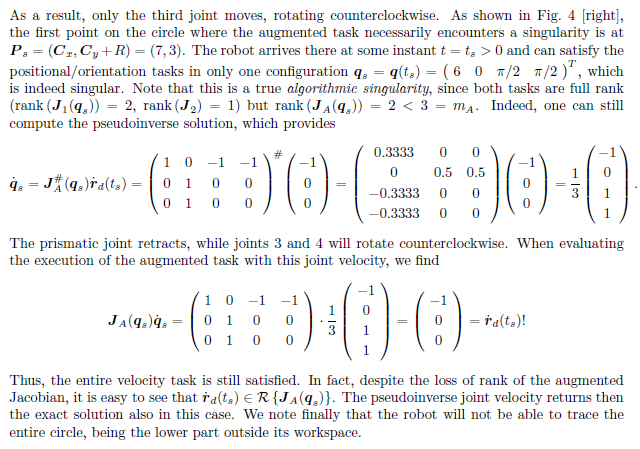

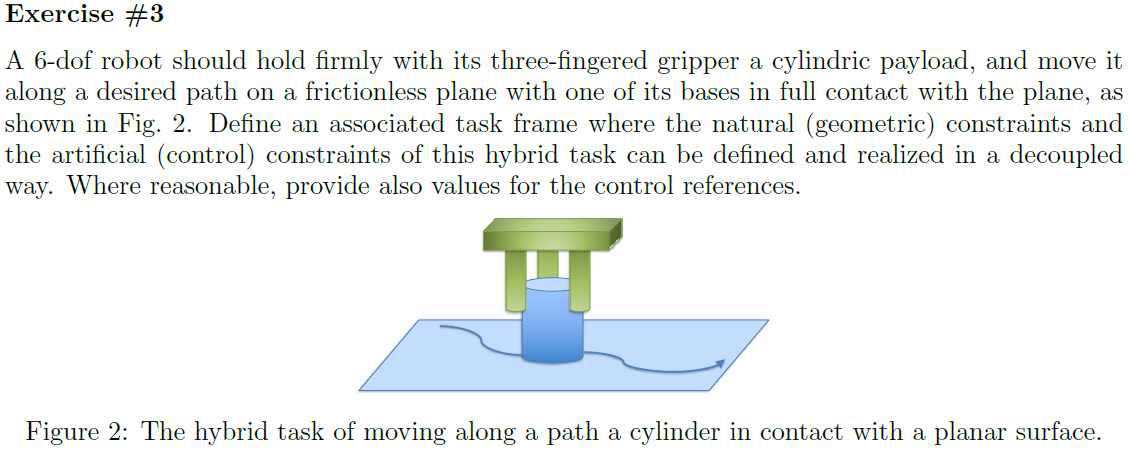

## natural cosntrains

## Check one note

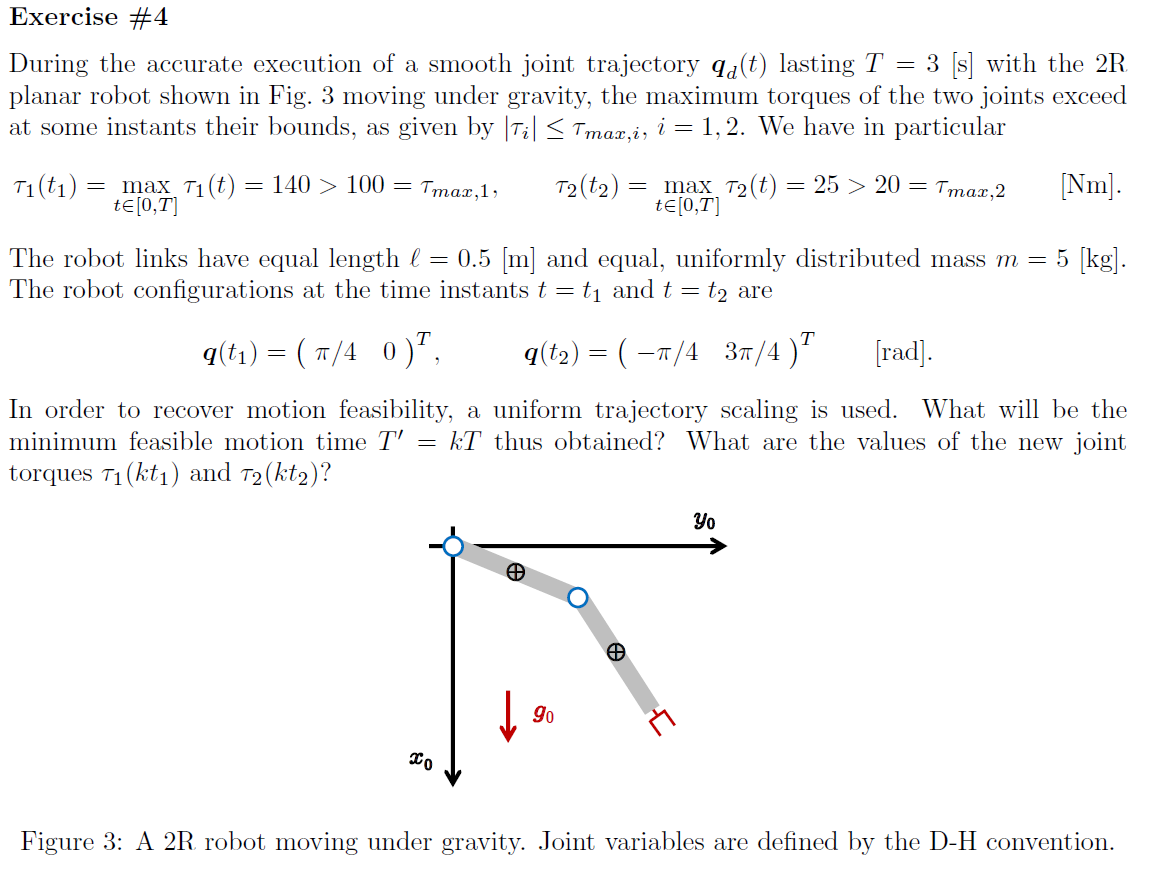

% % This part is isolated from previous section
% clear;clc;
% 
% % syms k q1(t) q2(t) q3(t)
% sigma = [0,0];
% R2Robot=['rr';'xx';sigma]
% n = length(sigma);
% % t = sym('t', 'real');
% q = sym('q_', [n 1],'real');
% qd = sym('q_dot_', [n 1],'real');
% qdd = sym('q_ddot_', [n 1],'real');
% %
% dc = sym('dc_', [n 1],'real');
% % k = sym('k', [n 1],'real');
% l = sym('l_', [n 1],'real');
% m = sym('m_', [n 1],'real');
% I = sym('I_', [n 1],'real');
% alpha_angle=sym('alpha','real')
% g0 = sym('g0','real');
% g=[g0,0,0]';
% 
% z = Gen_param(n);
% z.sigmaD=R2Robot;
% z.l=l;
% z.q=q;
% z.q_dot=qd;
% z.dc=dc;
% z.m=m;
% z.I=I;
% z.methodD=1;
% % z.dhTable=[]
% z.firstParam='alpha';
% % z.rc=[];
% % z.movingframes=[];
% z.angle_=sym(zeros(1,n));
% l_0=sym('l','real')
% m_0=sym('m','real')
% z.opt_expr={[l;dc],[l_0,l_0,l_0/2,l_0/2]'};%not necessary
% l_=[l_0,l_0]';
% m_=[m_0,m_0]';
% % z.rcdefined=true;

## axis offset

% 
% % h=sym('h','real')
% % %x,y,z
% % z.xyx_offset=sym(zeros(3,n));
% % z.xyx_offset(:,1)=[0,0*h,0]'%

% %Global q reference?
% % clear
% % z.q_global
% z.global_q_reference=false;
% if(z.global_q_reference)
%     [z.q_global,z.q_dot_global]=convert_local2global_q(z.q,z.q_dot,z.sigmaD);
% end

% 
% %
% %
% % xyonly=true
% % [f,J,V,J_ps,PCVar,PC_EEShort,VarShortRobot]= getGenericPC_EE2(R2Robot,l,q,qd,dc,m,I,xyonly)
% % VarShortRobot.M
% % angle_desired=[0,0]
% % l(1)=0
% [Pc,vc,w,T,Ti,M,VarShortRobot,Trans] = getGenericPC2(z);

% M
% Pc
% simplify((Ti'))
% vc
% simplify(Trans.PTotal)
% Trans.PPartial{:}

% isMotor=false
% [g_q, PE, U,g_q_short,PE_short] = getGravityWithPc(Pc, q, l_, m_, dc, g, isMotor);

% g_q
% U{:}
% 

## evaluating gravity torques

## t1

% q1_=[pi/4,0]'
% l_def=sym('l','real')
% m_def=sym('m','real')
% l_=0.5
% m_=5
% g0_=9.81
% 
% vars2replace=[l_def;m_def;g0;q]
% vars2replace_=[l_;m_;g0_;q1_]
% g_q_t1_=vpa(subs(g_q,vars2replace,vars2replace_))

## t2

% q2_=[-pi/4,3*pi/4]'
% vars2replace=[l_def;m_def;g0;q]
% vars2replace_=[l_;m_;g0_;q2_]
% g_q_t2_=vpa(subs(g_q,vars2replace,vars2replace_))

## evaluating

% g1_torque_=g_q_t1_(1)
% g2_torque_=g_q_t2_(2)
% tau_max_1=100;
% tau_max_2=20;
% tau_q1_t1=140;
% tau_q2_t2=25;
% k1=sqrt((tau_q1_t1-g1_torque_)/(tau_max_1-g1_torque_))
% k2=sqrt((tau_q2_t2-g2_torque_)/(tau_max_2-g2_torque_))%% this is the maximun k we have to use this

## recomputing new maximun torques

% tau_q1_tk=(tau_q1_t1-g1_torque_)/k2^2+g1_torque_
% tau_q2_tk=(tau_q2_t2-g2_torque_)/k2^2+g2_torque_

## Exercise 5

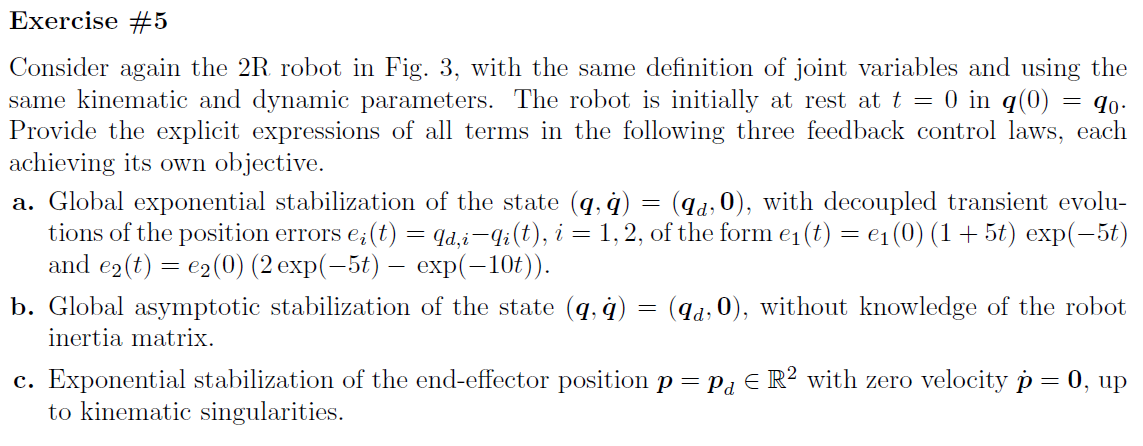

% This part is isolated from previous section
clear;clc

% syms k q1(t) q2(t) q3(t)
sigma = [0,0];
n = length(sigma);
% t = sym('t', 'real');
q = sym('q_', [n 1],'real');
qd = sym('q_dot_', [n 1],'real');
qdd = sym('q_ddot_', [n 1],'real');
%
dc = sym('dc_', [n 1],'real');
% k = sym('k', [n 1],'real');
l = sym('l_', [n 1],'real');
m = sym('m_', [n 1],'real');
I = sym('I_', [n 1],'real');
alpha_angle=sym('alpha','real')

$$alpha\_angle = \alpha$$

g0 = sym('g0','real');
g=[g0,0,0]';

defining z struct

R2Robot=['rr';'xx';sigma]

R2Robot = 3×2 char array
    'rr'
    'xx'
    '  '


z = Gen_param(n);
z.sigmaD=R2Robot;
z.l=l;
z.q=q;
z.q_dot=qd;
z.dc=dc;
z.m=m;
z.I=I;
z.methodD=1;
% z.dhTable=[]
z.firstParam='alpha';
% z.rc=[];
% z.movingframes=[];
z.angle_=sym(zeros(1,n));
l_0=sym('l','real')

$$l\_0 = l$$

m_0=sym('m','real')

$$m\_0 = m$$

z.opt_expr={[l;dc],[l_0,l_0,l_0/2,l_0/2]'};%not necessary
l_=[l_0,l_0]';
m_=[m_0,m_0]';
% z.rcdefined=true;

## axis offset


% h=sym('h','real')
% %x,y,z
% z.xyx_offset=sym(zeros(3,n));
% z.xyx_offset(:,1)=[0,0*h,0]'%

% %Global q reference?
% % clear
% % z.q_global
% z.global_q_reference=false
% if(z.global_q_reference)
%     [z.q_global,z.q_dot_global]=convert_local2global_q(z.q,z.q_dot,z.sigmaD)
% end


%
%
% xyonly=true
% [f,J,V,J_ps,PCVar,PC_EEShort,VarShortRobot]= getGenericPC_EE2(R2Robot,l,q,qd,dc,m,I,xyonly)
% VarShortRobot.M
% angle_desired=[0,0]
% l(1)=0
[Pc,vc,w,T,Ti,M,VarShortRobot,Trans] = getGenericPC2(z);

rcdefined = logical
   1


z = struct with fields:
                  sigmaD: [3×2 char]
                       l: [2×1 sym]
                      l_: []
                       q: [2×1 sym]
                   q_dot: [2×1 sym]
                      q_: []
                  q_dot_: []
                      dc: [2×1 sym]
                       m: [2×1 sym]
                       I: [2×1 sym]
                 methodD: 1
                 dhTable: []
              firstParam: 'alpha'
                       t: t
                      rc: []
            movingframes: 0
                       n: 2
                  angle_: [0    0]
               rcdefined: 1
                opt_expr: {[4×1 sym]  [4×1 sym]}
                collides: []
                joint_on: 1
                  xyonly: 0
    prismatic_CoM_method: [1 1]
               dc_method: 0
                     g_q: []
                 isMotor: 0
                       g: []
            task_defined: {}
              xyx_offset: []
      global_q_reference: 0
   

si falla aquí está el error


$$a = l_{1}$$

d = 0

$$a = l_{2}$$

d = 0

method with PC , pay attention!
moving frames OFF!!


$$Ti = \frac{{{\dot{q}}_{1}}^{2}\,\left(m_{1}\,l^{2}+4\,I_{1}\right)}{8}$$

moving frames OFF!!


$$Ti = \left(\begin{array}{cc} \frac{{{\dot{q}}_{1}}^{2}\,\left(m_{1}\,l^{2}+4\,I_{1}\right)}{8} & \frac{I_{2}\,{\left({\dot{q}}_{1}+{\dot{q}}_{2}\right)}^{2}}{2}+\frac{m_{2}\,\left(\frac{l^{2}\,{{\dot{q}}_{2}}^{2}}{4}+\frac{l^{2}\,{{\dot{q}}_{1}}^{2}\,\left(4\,\cos\left(q_{2}\right)+5\right)}{4}+\frac{l^{2}\,{\dot{q}}_{1}\,{\dot{q}}_{2}\,\left(4\,\cos\left(q_{2}\right)+2\right)}{4}\right)}{2} \end{array}\right)$$

M

$$M = \left(\begin{array}{cc} I_{1}+I_{2}+\frac{l^{2}\,m_{1}}{4}+\frac{5\,l^{2}\,m_{2}}{4}+l^{2}\,m_{2}\,\cos\left(q_{2}\right) & I_{2}+\frac{l^{2}\,m_{2}}{4}+\frac{l^{2}\,m_{2}\,\cos\left(q_{2}\right)}{2}\\ I_{2}+\frac{l^{2}\,m_{2}}{4}+\frac{l^{2}\,m_{2}\,\cos\left(q_{2}\right)}{2} & \frac{m_{2}\,l^{2}}{4}+I_{2} \end{array}\right)$$

Pc

$$Pc = \left(\begin{array}{cc} \frac{l\,\cos\left(q_{1}\right)}{2} & \frac{l\,\cos\left(q_{1}+q_{2}\right)}{2}+l\,\cos\left(q_{1}\right)\\ \frac{l\,\sin\left(q_{1}\right)}{2} & \frac{l\,\sin\left(q_{1}+q_{2}\right)}{2}+l\,\sin\left(q_{1}\right)\\ 0 & 0 \end{array}\right)$$

simplify((Ti'))

$$ans = \left(\begin{array}{c} \frac{{{\dot{q}}_{1}}^{2}\,\left(m_{1}\,l^{2}+4\,I_{1}\right)}{8}\\ \frac{I_{2}\,{\left({\dot{q}}_{1}+{\dot{q}}_{2}\right)}^{2}}{2}+\frac{m_{2}\,\left(\frac{l^{2}\,{{\dot{q}}_{2}}^{2}}{4}+\frac{l^{2}\,{{\dot{q}}_{1}}^{2}\,\left(4\,\cos\left(q_{2}\right)+5\right)}{4}+\frac{l^{2}\,{\dot{q}}_{1}\,{\dot{q}}_{2}\,\left(4\,\cos\left(q_{2}\right)+2\right)}{4}\right)}{2} \end{array}\right)$$

vc

$$vc = \left(\begin{array}{cc} -\frac{l\,{\dot{q}}_{1}\,\sin\left(q_{1}\right)}{2} & -{\dot{q}}_{1}\,\left(\frac{l\,\sin\left(q_{1}+q_{2}\right)}{2}+l\,\sin\left(q_{1}\right)\right)-\frac{l\,{\dot{q}}_{2}\,\sin\left(q_{1}+q_{2}\right)}{2}\\ \frac{l\,{\dot{q}}_{1}\,\cos\left(q_{1}\right)}{2} & {\dot{q}}_{1}\,\left(\frac{l\,\cos\left(q_{1}+q_{2}\right)}{2}+l\,\cos\left(q_{1}\right)\right)+\frac{l\,{\dot{q}}_{2}\,\cos\left(q_{1}+q_{2}\right)}{2}\\ 0 & 0 \end{array}\right)$$

simplify(Trans.PTotal)

$$ans = \left(\begin{array}{c} l\,\left(\cos\left(q_{1}+q_{2}\right)+\cos\left(q_{1}\right)\right)\\ l\,\left(\sin\left(q_{1}+q_{2}\right)+\sin\left(q_{1}\right)\right)\\ 0 \end{array}\right)$$

Trans.PPartial{:}

$$ans = \left(\begin{array}{c} l\,\cos\left(q_{1}\right)\\ l\,\sin\left(q_{1}\right)\\ 0 \end{array}\right)$$

$$ans = \left(\begin{array}{c} l\,\cos\left(q_{2}\right)\\ l\,\sin\left(q_{2}\right)\\ 0 \end{array}\right)$$

isMotor=false

isMotor = logical
   0


[g_q, PE, U,g_q_short,PE_short] = getGravityWithPc(Pc, q, l_, m_, dc, g, isMotor)

*** Computation of Potential Energy (Jacobian-based method) 


$$qall\_sincos\_comb = \left(\begin{array}{cccccc} \sin\left(q_{1}\right) & \sin\left(q_{2}\right) & \sin\left(q_{1}+q_{2}\right) & \cos\left(q_{1}\right) & \cos\left(q_{2}\right) & \cos\left(q_{1}+q_{2}\right) \end{array}\right)$$

$$PE = -\frac{g_{0}\,l\,m\,\left(\cos\left(q_{1}+q_{2}\right)+3\,\cos\left(q_{1}\right)\right)}{2}$$

$$PE\_short = -\frac{g_{0}\,l\,m\,\left(\cos\left(q_{1}+q_{2}\right)+3\,\cos\left(q_{1}\right)\right)}{2}$$

$$g\_q\_short = \left(\begin{array}{c} \frac{g_{0}\,l\,m\,\left(\sin\left(q_{1}+q_{2}\right)+3\,\sin\left(q_{1}\right)\right)}{2}\\ \frac{g_{0}\,l\,m\,\sin\left(q_{1}+q_{2}\right)}{2} \end{array}\right)$$

$$g\_q = \left(\begin{array}{c} \frac{g_{0}\,l\,m\,\left(\sin\left(q_{1}+q_{2}\right)+3\,\sin\left(q_{1}\right)\right)}{2}\\ \frac{g_{0}\,l\,m\,\sin\left(q_{1}+q_{2}\right)}{2} \end{array}\right)$$

$$PE = -\frac{g_{0}\,l\,m\,\left(\cos\left(q_{1}+q_{2}\right)+3\,\cos\left(q_{1}\right)\right)}{2}$$

U = 1×2 cell array
    {[-(g0*l*m*cos(q_1))/2]}    {[-(g0*l*m*(cos(q_1 + q_2) + 2*cos(q_1)))/2]}


$$g\_q\_short = \left(\begin{array}{c} \frac{g_{0}\,l\,m\,\left(\sin\left(q_{1}+q_{2}\right)+3\,\sin\left(q_{1}\right)\right)}{2}\\ \frac{g_{0}\,l\,m\,\sin\left(q_{1}+q_{2}\right)}{2} \end{array}\right)$$

$$PE\_short = -\frac{g_{0}\,l\,m\,\left(\cos\left(q_{1}+q_{2}\right)+3\,\cos\left(q_{1}\right)\right)}{2}$$

g_q

$$g\_q = \left(\begin{array}{c} \frac{g_{0}\,l\,m\,\left(\sin\left(q_{1}+q_{2}\right)+3\,\sin\left(q_{1}\right)\right)}{2}\\ \frac{g_{0}\,l\,m\,\sin\left(q_{1}+q_{2}\right)}{2} \end{array}\right)$$

U{:}

$$ans = -\frac{g_{0}\,l\,m\,\cos\left(q_{1}\right)}{2}$$

$$ans = -\frac{g_{0}\,l\,m\,\left(\cos\left(q_{1}+q_{2}\right)+2\,\cos\left(q_{1}\right)\right)}{2}$$

## control

## a)


t=sym('t','real');
s=sym('s','real');
e_1_0=sym('e_1_0','real');
e_2_0=sym('e_2_0','real');
e_=[e_1_0*(1+5*t)*exp(-5*t);e_2_0*(2*exp(-5*t)-exp(-10*t))]

$$e\_ = \left(\begin{array}{c} e_{1,0}\,{\mathrm{e}}^{-5\,t}\,\left(5\,t+1\right)\\ e_{2,0}\,\left(2\,{\mathrm{e}}^{-5\,t}-{\mathrm{e}}^{-10\,t}\right) \end{array}\right)$$

z_global_exponential = feedback_linearization_control_global_exponential(z,e_)

z = struct with fields:
                  sigmaD: [3×2 char]
                       l: [2×1 sym]
                      l_: []
                       q: [2×1 sym]
                   q_dot: [2×1 sym]
                      q_: []
                  q_dot_: []
                      dc: [2×1 sym]
                       m: [2×1 sym]
                       I: [2×1 sym]
                 methodD: 1
                 dhTable: []
              firstParam: 'alpha'
                       t: t
                      rc: []
            movingframes: 0
                       n: 2
                  angle_: [0    0]
               rcdefined: 1
                opt_expr: {[4×1 sym]  [4×1 sym]}
                collides: []
                joint_on: 1
                  xyonly: 0
    prismatic_CoM_method: [1 1]
               dc_method: 0
                     g_q: []
                 isMotor: 0
                       g: []
            task_defined: {}
              xyx_offset: []
      global_q_reference: 0
   

z = struct with fields:
                  sigmaD: [3×2 char]
                       l: [2×1 sym]
                      l_: []
                       q: [2×1 sym]
                   q_dot: [2×1 sym]
                      q_: []
                  q_dot_: []
                      dc: [2×1 sym]
                       m: [2×1 sym]
                       I: [2×1 sym]
                 methodD: 1
                 dhTable: []
              firstParam: 'alpha'
                       t: t
                      rc: []
            movingframes: 0
                       n: 2
                  angle_: [0    0]
               rcdefined: 1
                opt_expr: {[4×1 sym]  [4×1 sym]}
                collides: []
                joint_on: 1
                  xyonly: 0
    prismatic_CoM_method: [1 1]
               dc_method: 0
                     g_q: []
                 isMotor: 0
                       g: []
            task_defined: {}
              xyx_offset: []
      global_q_reference: 0
   

    "global asymptotic stabilization"



z = struct with fields:
                  sigmaD: [3×2 char]
                       l: [2×1 sym]
                      l_: []
                       q: [2×1 sym]
                   q_dot: [2×1 sym]
                      q_: []
                  q_dot_: []
                      dc: [2×1 sym]
                       m: [2×1 sym]
                       I: [2×1 sym]
                 methodD: 1
                 dhTable: []
              firstParam: 'alpha'
                       t: t
                      rc: []
            movingframes: 0
                       n: 2
                  angle_: [0    0]
               rcdefined: 1
                opt_expr: {[4×1 sym]  [4×1 sym]}
                collides: []
                joint_on: 1
                  xyonly: 0
    prismatic_CoM_method: [1 1]
               dc_method: 0
                     g_q: []
                 isMotor: 0
                       g: []
            task_defined: {}
              xyx_offset: []
      global_q_reference: 0
   

    "replacing values"



z_global_exponential = struct with fields:
                  sigmaD: [3×2 char]
                       l: [2×1 sym]
                      l_: []
                       q: [2×1 sym]
                   q_dot: [2×1 sym]
                      q_: []
                  q_dot_: []
                      dc: [2×1 sym]
                       m: [2×1 sym]
                       I: [2×1 sym]
                 methodD: 1
                 dhTable: []
              firstParam: 'alpha'
                       t: t
                      rc: []
            movingframes: 0
                       n: 2
                  angle_: [0    0]
               rcdefined: 1
                opt_expr: {[4×1 sym]  [4×1 sym]}
                collides: []
                joint_on: 1
                  xyonly: 0
    prismatic_CoM_method: [1 1]
               dc_method: 0
                     g_q: []
                 isMotor: 0
                       g: []
            task_defined: {}
              xyx_offset: []
      global

K_D=diag(sym('K_D_',[2,1],'real'))

$$K\_D = \left(\begin{array}{cc} K_{D,1} & 0\\ 0 & K_{D,2} \end{array}\right)$$

K_P=diag(sym('K_P_',[2,1],'real'))

$$K\_P = \left(\begin{array}{cc} K_{P,1} & 0\\ 0 & K_{P,2} \end{array}\right)$$

to_collect=[exp(-5*t),e_1_0,e_2_0];%,K_D(:)',K_P(:)'];
e_=collect(z_global_exponential.e_,to_collect)

$$e\_ = \left(\begin{array}{c} \left(5\,t+1\right)\,{\mathrm{e}}^{-5\,t}\,e_{1,0}\\ 2\,{\mathrm{e}}^{-5\,t}\,e_{2,0}+\left(-{\mathrm{e}}^{-10\,t}\right)\,e_{2,0} \end{array}\right)$$

e_dot_=collect(z_global_exponential.e_dot_,to_collect)

$$e\_dot\_ = \left(\begin{array}{c} \left(-25\,t\right)\,{\mathrm{e}}^{-5\,t}\,e_{1,0}\\ -10\,{\mathrm{e}}^{-5\,t}\,e_{2,0}+\left(10\,{\mathrm{e}}^{-10\,t}\right)\,e_{2,0} \end{array}\right)$$

e_ddot_=collect(z_global_exponential.e_ddot_,to_collect)

$$e\_ddot\_ = \left(\begin{array}{c} \left(125\,t-25\right)\,{\mathrm{e}}^{-5\,t}\,e_{1,0}\\ 50\,{\mathrm{e}}^{-5\,t}\,e_{2,0}+\left(-100\,{\mathrm{e}}^{-10\,t}\right)\,e_{2,0} \end{array}\right)$$

laplace(exp(-5*t))

$$ans = \frac{1}{s+5}$$

laplace((t))

$$ans = \frac{1}{s^{2}}$$

expand(laplace(simplify(z_global_exponential.law_(1))))

$$ans = \frac{10\,K_{\mathrm{P1}}\,e_{1,0}}{s^{2}+10\,s+25}-\frac{25\,K_{\mathrm{D1}}\,e_{1,0}}{s^{2}+10\,s+25}-\frac{25\,e_{1,0}\,s}{s^{2}+10\,s+25}+\frac{K_{\mathrm{P1}}\,e_{1,0}\,s}{s^{2}+10\,s+25}$$

collect(simplify(e_ddot_+K_D*e_dot_+K_P*e_),to_collect)

$$ans = \left(\begin{array}{c} \left(K_{P,1}+125\,t-25\,K_{D,1}\,t+5\,K_{P,1}\,t-25\right)\,{\mathrm{e}}^{-5\,t}\,e_{1,0}\\ \left({\mathrm{e}}^{-10\,t}\,\left(10\,K_{D,2}-K_{P,2}+50\,{\mathrm{e}}^{5\,t}-10\,K_{D,2}\,{\mathrm{e}}^{5\,t}+2\,K_{P,2}\,{\mathrm{e}}^{5\,t}-100\right)\right)\,e_{2,0} \end{array}\right)$$

## identifitying poles

a_law_=z_global_exponential.law_

$$a\_law\_ = \left(\begin{array}{c} e_{1,0}\,{\mathrm{e}}^{-5\,t}\,\left(K_{\mathrm{P1}}+125\,t-25\,K_{\mathrm{D1}}\,t+5\,K_{\mathrm{P1}}\,t-25\right)\\ e_{2,0}\,{\mathrm{e}}^{-10\,t}\,\left(10\,K_{\mathrm{D2}}-K_{\mathrm{P2}}+50\,{\mathrm{e}}^{5\,t}-10\,K_{\mathrm{D2}}\,{\mathrm{e}}^{5\,t}+2\,K_{\mathrm{P2}}\,{\mathrm{e}}^{5\,t}-100\right) \end{array}\right)$$

a_law_laplace=z_global_exponential.law_laplace_

$$a\_law\_laplace = \left(\begin{array}{c} -\frac{e_{1,0}\,\left(25\,K_{\mathrm{D1}}-10\,K_{\mathrm{P1}}+25\,s-K_{\mathrm{P1}}\,s\right)}{{\left(s+5\right)}^{2}}\\ -\frac{e_{2,0}\,\left(50\,K_{\mathrm{D2}}-15\,K_{\mathrm{P2}}+50\,s-K_{\mathrm{P2}}\,s\right)}{s^{2}+15\,s+50} \end{array}\right)$$


poles(a_law_laplace(1),s)

$$ans = -5$$

poles(a_law_laplace(2),s)

$$ans = \left(\begin{array}{c} -5\\ -10 \end{array}\right)$$

## another way... did't work haha

% % K_D=z_global_exponential.mK_D;
% % K_P=z_global_exponential.mK_P;
% % a_law_factors_1=factor(a_law_(1))
% % kp_1_sol=solve(a_law_factors_1(2)==0,[K_P(1);K_D(1)])
% % simplify(subs(a_law_factors_1(2),kp_1_sol))

## b)By hand